Load csv spreadsheet with all the data and show contents

Xall = readtable('Xall_figures.csv')

Xall = 2555×36 table
    Var1    participant_id    session_num    instance_num    attempt_num    treatment_cat    sahni_k      alpha       v_w_corr_pearson    mzn_props    attempt_submitted    time_on_task    length_of_sequence    num_unique_sets_in_seq    attempt_value    attempt_weight    solution_value    capacity    attempt_value_pct_solution    attempt_correct    len_sp_to_sol    ln_sp_first_tn_to_sol    ln_sp_last_tn_to_sol    num_items_overlap_first_tn_sol_set    num_items_overlap_last_tn_sol_set    alpha_attempt_set    mzn_props_attempt

Figure 1d

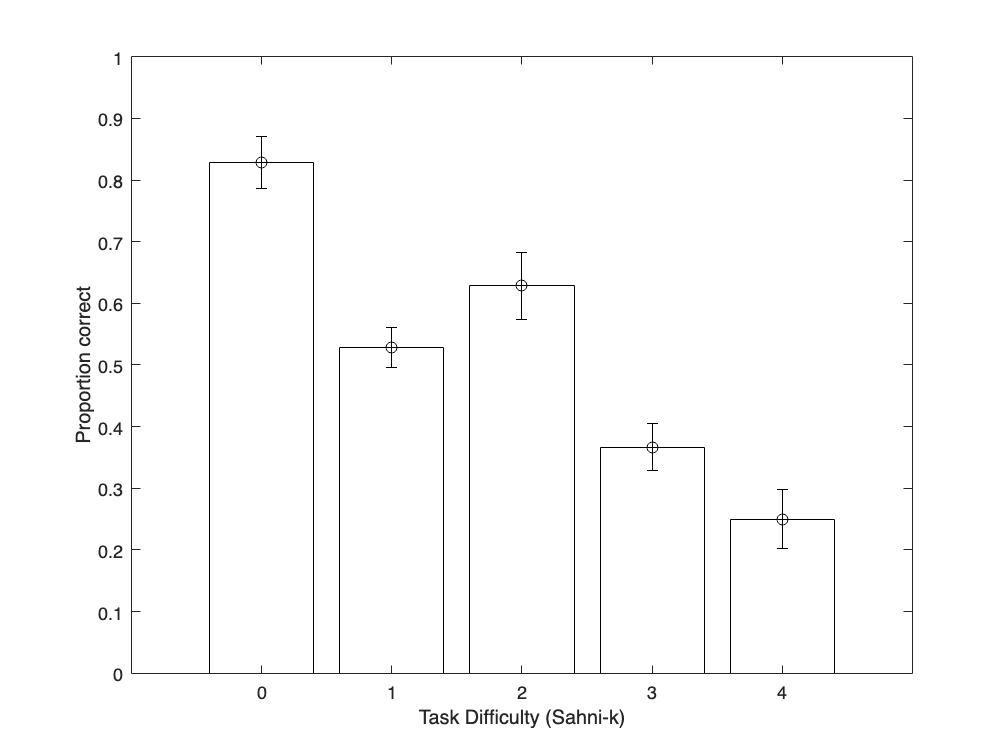

figure;
fs = find(Xall.sahni_k==0);
solf0 = Xall.attempt_correct(fs);
fs = find(Xall.sahni_k==1);
solf1 = Xall.attempt_correct(fs);
fs = find(Xall.sahni_k==2);
solf2 = Xall.attempt_correct(fs);
fs = find(Xall.sahni_k==3);
solf3 = Xall.attempt_correct(fs);
fs = find(Xall.sahni_k==4);
solf4 = Xall.attempt_correct(fs);
mnsolf = [mean(solf0) mean(solf1) mean(solf2) mean(solf3) mean(solf4)];
mnx = 0:1:4;
ste = mnsolf.*(1-mnsolf); % standard error computations
ste = ste./[length(solf0) length(solf1) length(solf2) length(solf3) length(solf4)];
ste = sqrt(ste);
bar(mnx,mnsolf,'w')
axis([-1 5 0 1])
xlabel('Task Difficulty (Sahni-k)')
ylabel('Proportion correct')
hold on;
% error bars (=/- 2 s.e.) 
errorbar(mnx,mnsolf,2.*ste,'ok')
hold off;

Figure 2a

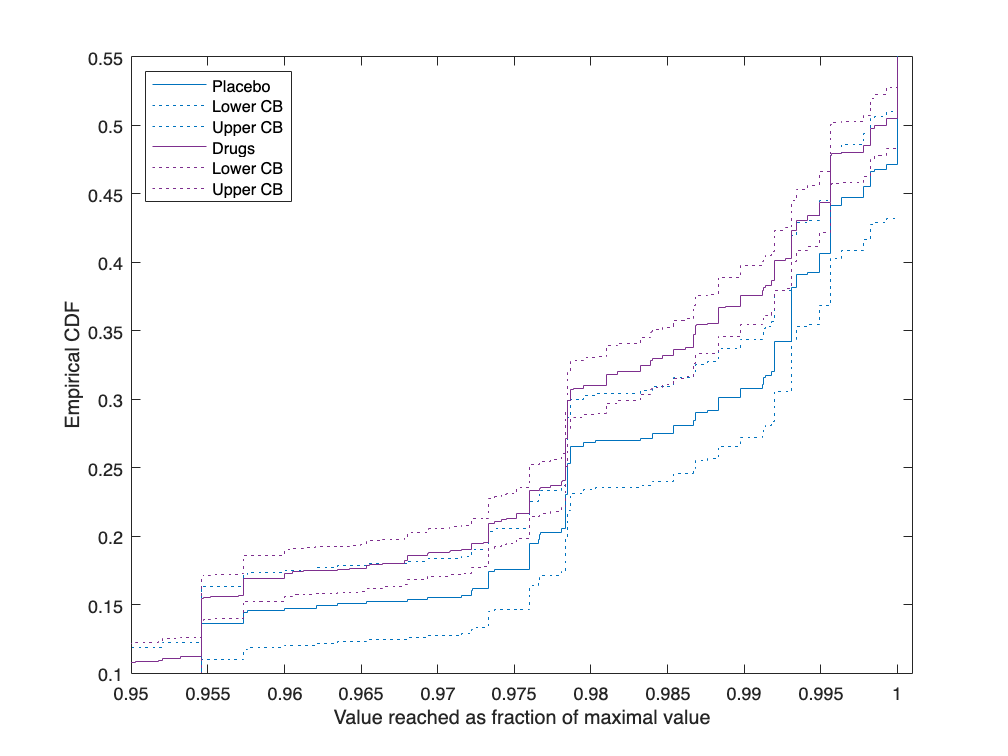

figure;
drugs = ['PLC','DEX','MOD','MPH'];
fs = find(Xall.treatment==0);
solf0 = Xall.attempt_value_pct_solution(fs);

fs = find(Xall.treatment==1);
solf1 = Xall.attempt_value_pct_solution(fs);

fs = find(Xall.treatment==2);
solf2 = Xall.attempt_value_pct_solution(fs);
 
fs = find(Xall.treatment==3);
solf3 = Xall.attempt_value_pct_solution(fs);

solfd = [solf1; solf2; solf3];

%boxplot(Xall.attempt_value_pct_solution,Xall.treatment)
%axis([-0.5 4.5 0.98 1.02])
%ecdf computes the confidence bounds using Greenwood's formula. 
ecdf(solf0,'bounds',"on")
axis([0.95 1.001 0.1 0.55])
hold on;
ecdf(solfd,'bounds',"on")
xlabel('Value reached as fraction of maximal value')
ylabel('Empirical CDF')
legend('Placebo','Lower CB','Upper CB','Drugs','Lower CB','Upper CB','Location',"northwest")
hold off;

Figure 2b

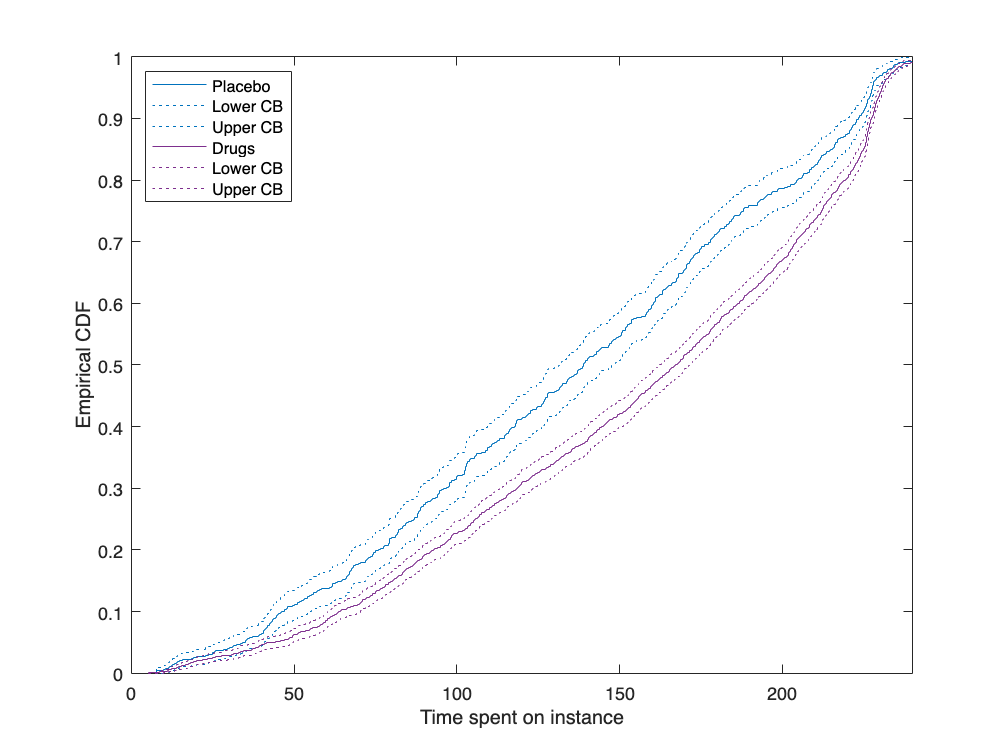

figure;
fs = find(Xall.treatment==0);
solf0 = Xall.time_on_task(fs);

fs = find(Xall.treatment==1);
solf1 = Xall.time_on_task(fs);

fs = find(Xall.treatment==2);
solf2 = Xall.time_on_task(fs);

fs = find(Xall.treatment==3);
solf3 = Xall.time_on_task(fs);

solfd = [solf1; solf2; solf3];

%boxplot(Xall.time_on_task,Xall.treatment)
ecdf(solf0,'bounds',"on")
axis([0 240 0 1])
hold on;
ecdf(solfd,'bounds',"on")
xlabel('Time spent on instance')
ylabel('Empirical CDF')
legend('Placebo','Lower CB','Upper CB','Drugs','Lower CB','Upper CB','Location',"northwest")
hold off;

Figure 2c

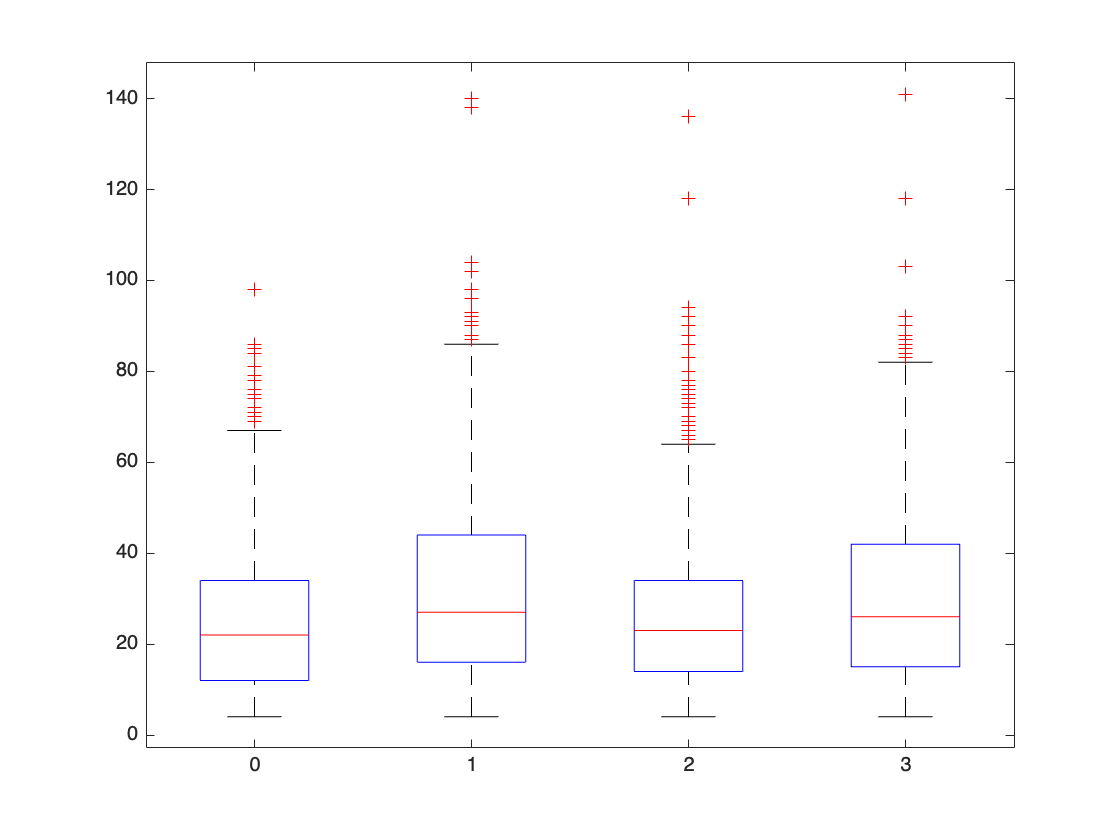

figure;
fs = find(Xall.treatment==0);
solf0 = Xall.length_of_sequence(fs);

fs = find(Xall.treatment==1);
solf1 = Xall.length_of_sequence(fs);

fs = find(Xall.treatment==2);
solf2 = Xall.length_of_sequence(fs);

fs = find(Xall.treatment==3);
solf3 = Xall.length_of_sequence(fs);

solfd = [solf1; solf2; solf3];

boxplot(Xall.length_of_sequence,Xall.treatment)

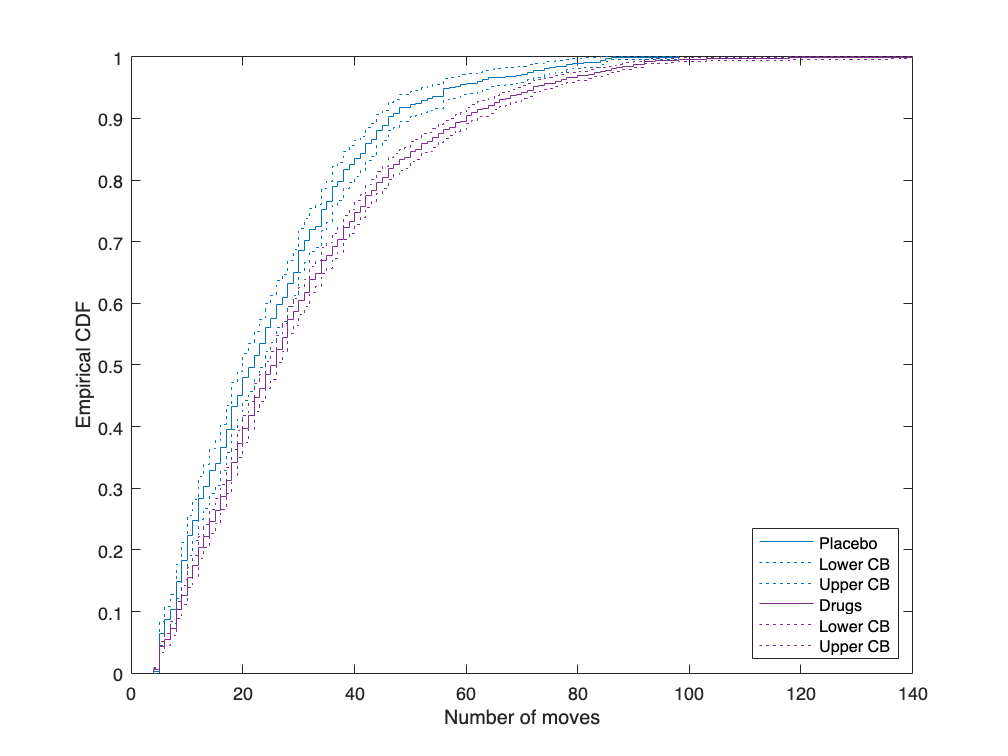


figure;
ecdf(solf0,'bounds',"on")
axis([0 140 0 1])
hold on;
ecdf(solfd,'bounds',"on")
xlabel('Number of moves')
ylabel('Empirical CDF')
legend('Placebo','Lower CB','Upper CB','Drugs','Lower CB','Upper CB','Location',"southeast")
hold off;

Figure 2d

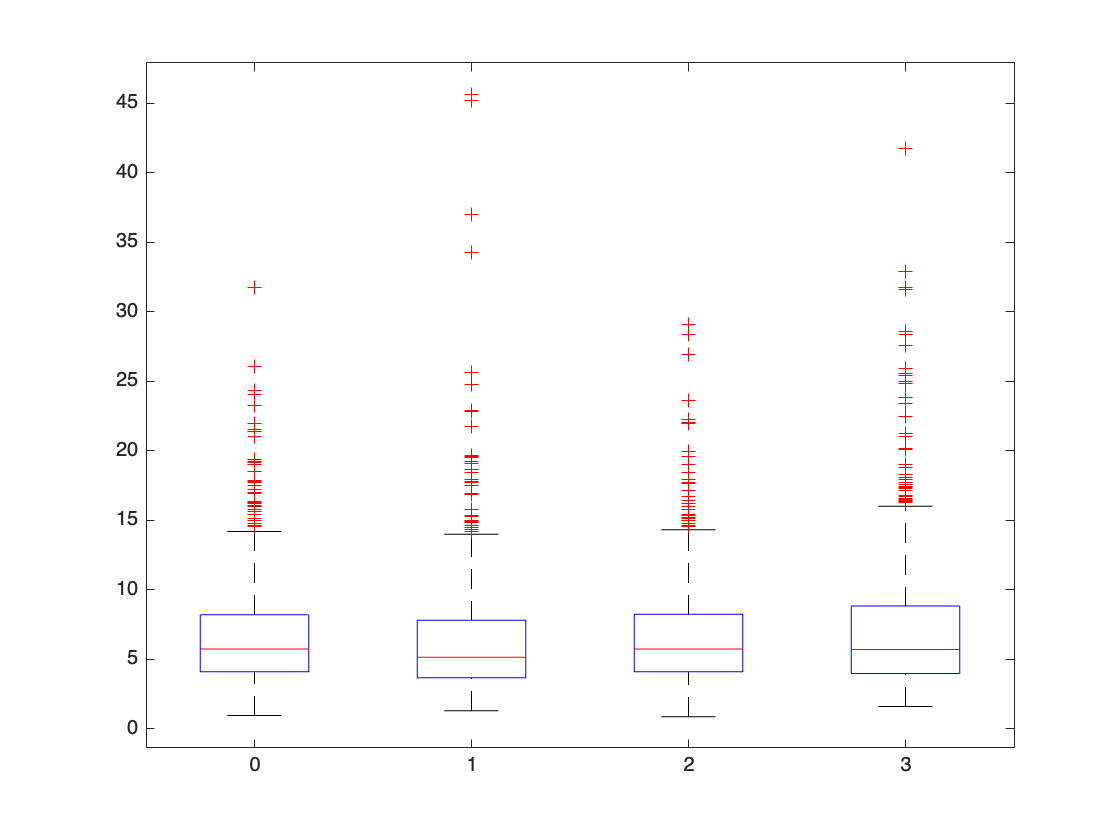

figure;
speed = Xall.time_on_task./Xall.length_of_sequence;
fs = find(Xall.treatment==0);
solf0 = speed(fs);

fs = find(Xall.treatment==1);
solf1 = speed(fs);

fs = find(Xall.treatment==2);
solf2 = speed(fs);

fs = find(Xall.treatment==3);
solf3 = speed(fs);

solfd = [solf1; solf2; solf3];

boxplot(speed,Xall.treatment)

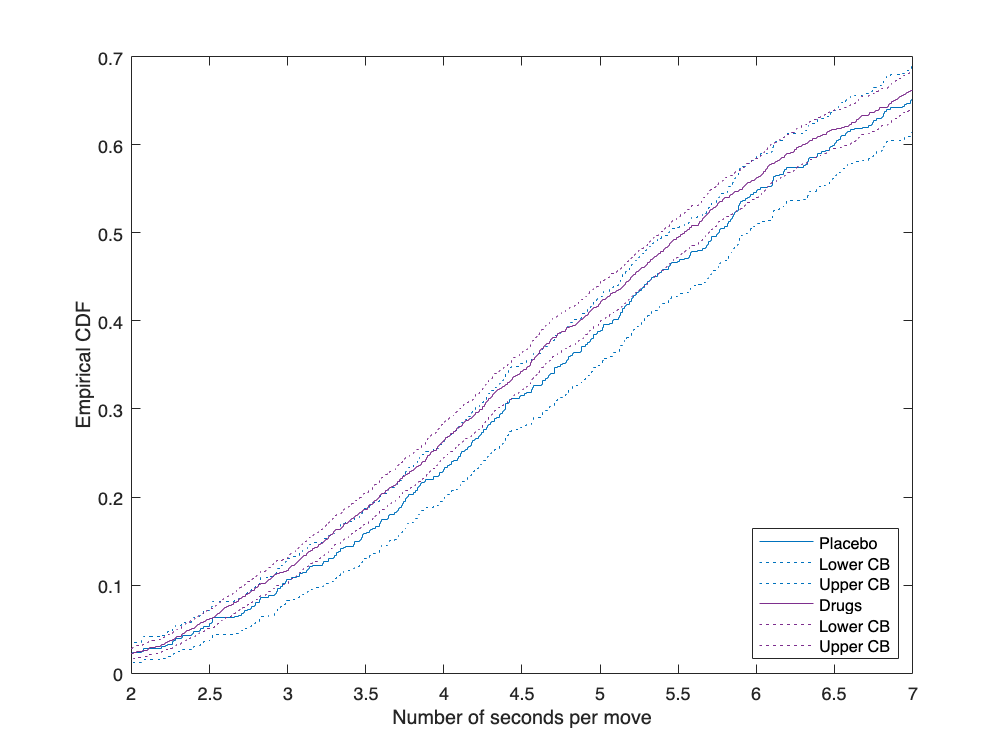


figure;
ecdf(solf0,'bounds',"on")
axis([2 7 0 0.7])
hold on;
ecdf(solfd,'bounds',"on")
xlabel('Number of seconds per move')
ylabel('Empirical CDF')
legend('Placebo','Lower CB','Upper CB','Drugs','Lower CB','Upper CB','Location',"southeast")
hold off;

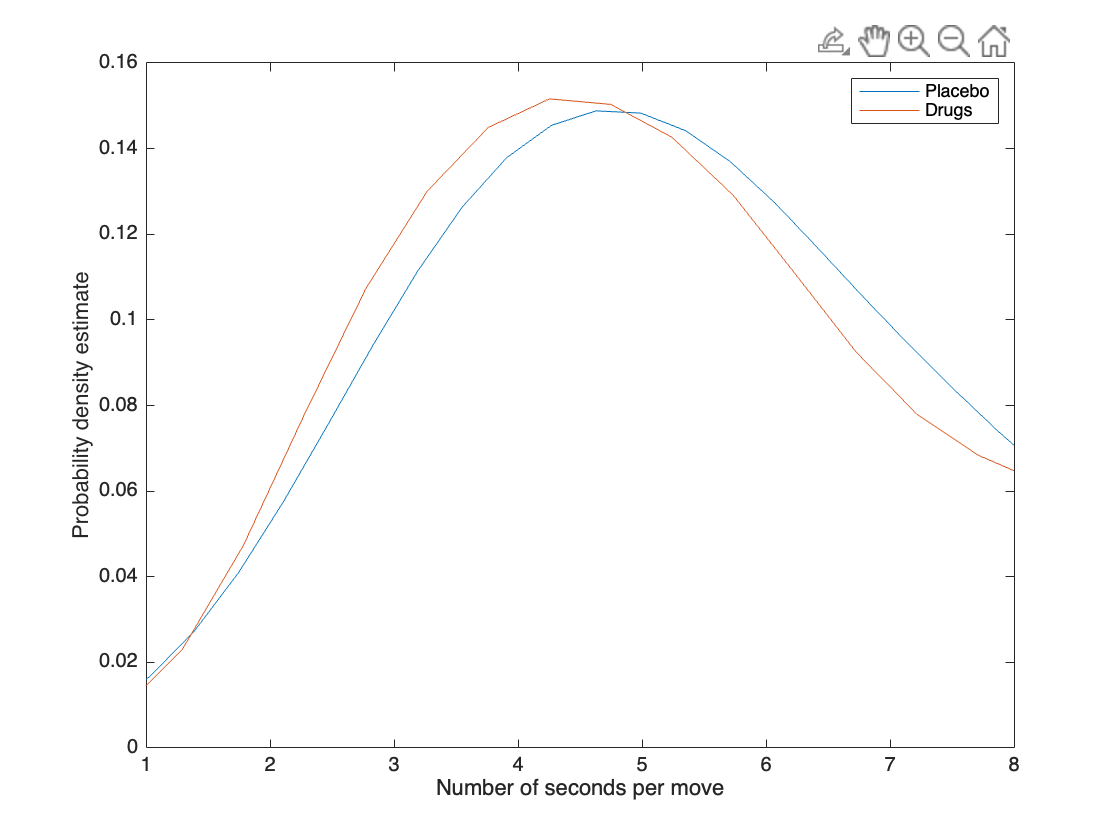


figure;
[f0,xi0] = ksdensity(solf0);
[fd,xid] = ksdensity(solfd);
plot(xi0,f0);
hold on;
plot(xid,fd);
axis([1 8 0 0.16])
xlabel('Number of seconds per move')
ylabel('Probability density estimate')
legend('Placebo','Drugs','Location',"northeast")
hold off;

Figure 3a; using alternative to boxplot (violinplot) from Holger Hoffmann (2022). Violin Plot (https://www.mathworks.com/matlabcentral/fileexchange/45134-violin-plot), MATLAB Central File Exchange. Retrieved February 10, 2022.

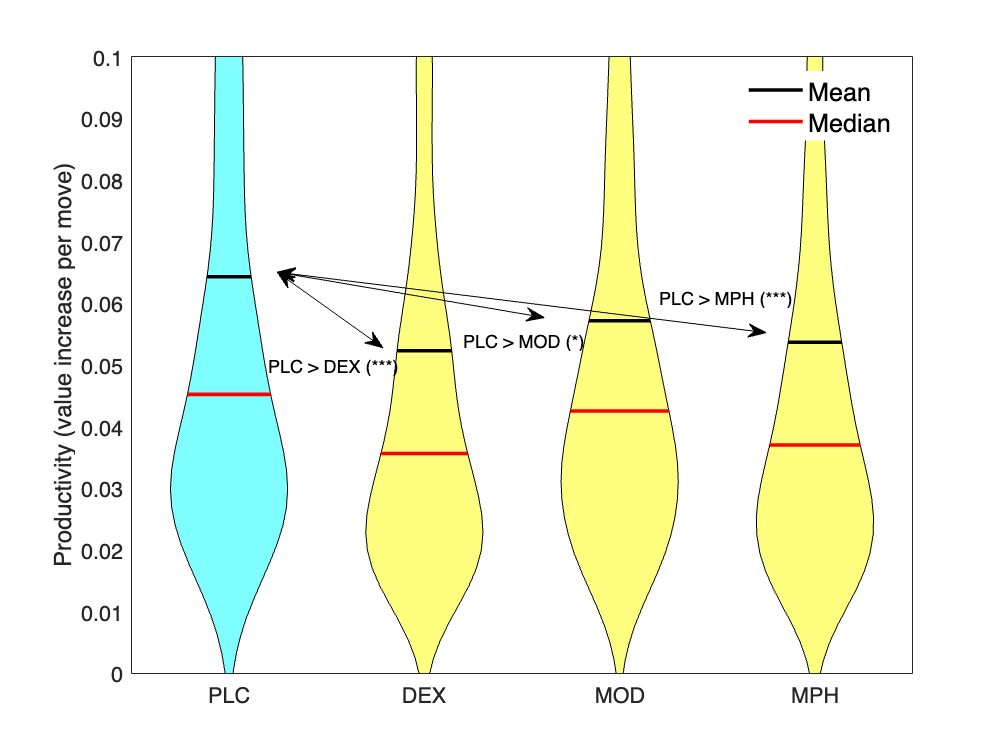

figure;
% boxplot(Xall.productivity,Xall.treatment)
fs = find(Xall.treatment==0);
solf0 = Xall.productivity(fs);

fs = find(Xall.treatment==1);
solf1 = Xall.productivity(fs);

fs = find(Xall.treatment==2);
solf2 = Xall.productivity(fs);

fs = find(Xall.treatment==3);
solf3 = Xall.productivity(fs);

produx = {solf0,solf1,solf2,solf3};
violin(produx,'xlabel',{'PLC','DEX','MOD','MPH'},'facecolor',[0 1 1; 1 1 0; 1 1 0; 1 1 0]);
axis([0.5 4.5 0 0.1])
ylabel('Productivity (value increase per move)')
annotation('doublearrow',[0.275,0.38],[0.64,0.54])
text(1.2,0.05,'PLC > DEX (***)')
annotation('doublearrow',[0.275,0.54],[0.64,0.58])
text(2.2,0.054,'PLC > MOD (*)')
annotation('doublearrow',[0.275,0.76],[0.64,0.56])
text(3.2,0.061,'PLC > MPH (***)')

Figure 3b

modelspec = 'productivity ~ 1 + treatment_cat + sahni_k + Complexity + mzn_props + (1 + treatment_cat | participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    productivity ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -9279.6    -9174.4    4657.8           -9315.6 

Fixed effects coefficients (95% CIs):
    Name                         Estimate       SE            tStat      DF      pValue         Lower          Upper      
    {'(Intercept)'      }            0.12712     0.0049474     25.695    2548    1.1381e-129        0.11742        0.13683
    


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl);
psi{1,1} % or stats{1,1}

ans = 1.0e-03 *

    0.5315   -0.0740   -0.0758   -0.2242
   -0.0740    0.2307   -0.0582    0.1872
   -0.0758   -0.0582    0.0599    0.0056
   -0.2242    0.1872    0.0056    0.3104


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl);
% intercept and slopes
% Association random effects PLC against MPH
figure;
p1 = plot(B(1:4:end),B(3:4:end),'ob')

p1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0228 0.0012 -0.0213 -0.0055 -0.0262 -0.0055 0.0344 -0.0095 0.0047 0.0078 0.0456 0.0199 -0.0182 -0.0322 0.0384 0.0346 -0.0239 0.0028 0.0413 -0.0039 0.0041 0.0216 -0.0082 -0.0132 -0.0176 -0.0123 -0.0156 0.0166 0.0062 0.0201 … ]
              YData: [-0.0019 0.0014 0.0049 -0.0050 0.0046 3.1342e-04 -2.1554e-04 0.0049 -6.3938e-04 0.0019 -0.0020 0.0016 0.0032 0.0042 -0.0116 -0.0203 0.0036 -0.0054 -0.0078 0.0075 0.0023 -0.0126 0.0080 0.0065 0.0017 -3.6988e-04 0.0013 -0.0032 … ]

  Show all properties


xlabel('Deviation from mean productivity under PLC')
ylabel('Deviation from mean productivity under MPH')
axis([-0.04 0.05 -0.04 0.05])
hold on;
bigX = [ones(length(B(3:4:end)),1), B(1:4:end)];
[b bint] = regress(B(3:4:end),bigX,0.001)

b =     0.0000
   -0.1343


bint =    -0.0029    0.0029
   -0.2632   -0.0054


Bhat = bigX*b;
p2 = plot(B(1:4:end),Bhat,'-r')

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0228 0.0012 -0.0213 -0.0055 -0.0262 -0.0055 0.0344 -0.0095 0.0047 0.0078 0.0456 0.0199 -0.0182 -0.0322 0.0384 0.0346 -0.0239 0.0028 0.0413 -0.0039 0.0041 0.0216 -0.0082 -0.0132 -0.0176 -0.0123 -0.0156 0.0166 0.0062 0.0201 … ]
              YData: [0.0031 -1.5763e-04 0.0029 7.3577e-04 0.0035 7.4480e-04 -0.0046 0.0013 -6.3548e-04 -0.0010 -0.0061 -0.0027 0.0024 0.0043 -0.0052 -0.0046 0.0032 -3.7508e-04 -0.0055 5.2008e-04 -5.5271e-04 -0.0029 0.0011 0.0018 0.0024 0.0016 0.0021 … ]

  Show <a href="matlab:if exist('p2', 'var'), matlab.graphics.internal.getForDisplay('p2', p2, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p2'), end">all properties</

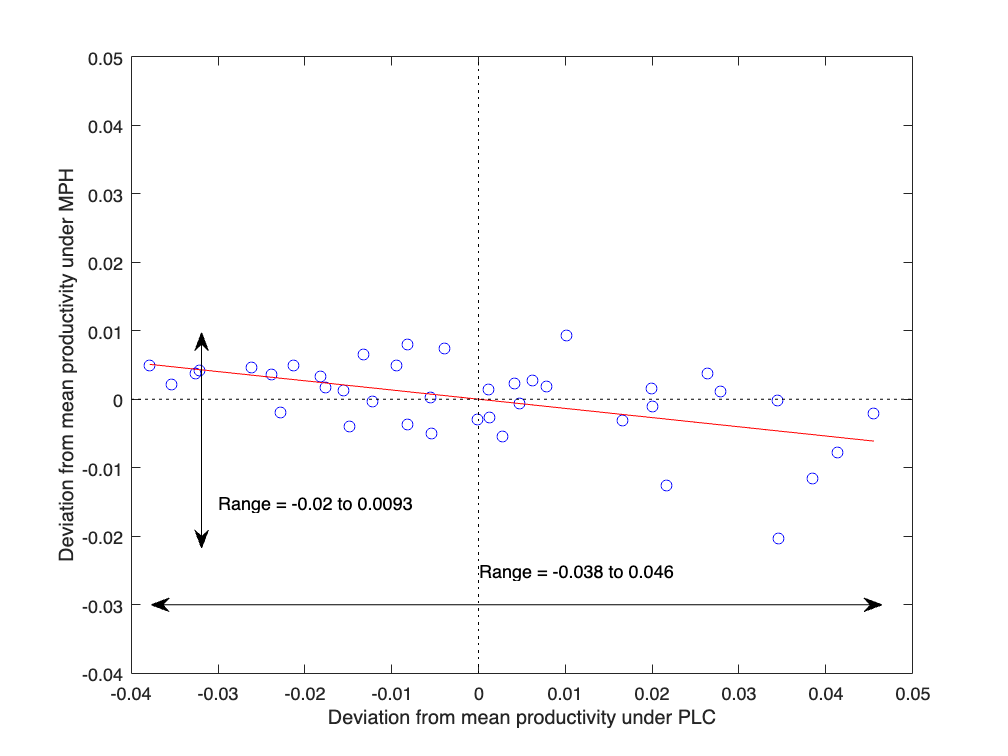

%legend('Individuals','OLS Fit (p < 0.001)')
ymin = min(B(3:4:end));
ymax = max(B(3:4:end));
annotation('doublearrow',[0.2,0.2],[0.275,0.56])
ymin = num2str(ymin,2);
ymax = num2str(ymax,2);
tkst = ['Range = ', ymin, ' to ', ymax];
text(-0.03,-0.015,tkst)
ymin = min(B(1:4:end));
ymax = max(B(1:4:end));
annotation('doublearrow',[0.15,0.875],[0.2,0.2])
ymin = num2str(ymin,2);
ymax = num2str(ymax,2);
tkst = ['Range = ', ymin, ' to ', ymax];
text(0,-0.025,tkst)
plot([-0.04,0.05],[0 0],':k')
plot([0 0],[-0.04 0.05],':k')
hold off;

Wilcoxon signed-rank statistic for paired differences of SQUARES

y2 = B(3:4:end).^2;
x2 = B(1:4:end).^2;
diffyx = y2-x2;
p = signrank(diffyx)

p = 3.2612e-07

Figure 3c

figure;
plot(B(2:4:end),B(4:4:end),'ob')
xlabel('Deviation from mean productivity under DEX')
ylabel('Deviation from mean productivity under MOD')
axis([-0.035 0.04 -0.035 0.04])
hold on;
bigX = [ones(length(B(2:4:end)),1), B(2:4:end)];
[b bint] = regress(B(4:4:end),bigX,0.001)

b =     0.0000
    0.8782


bint =    -0.0055    0.0055
    0.4501    1.3062


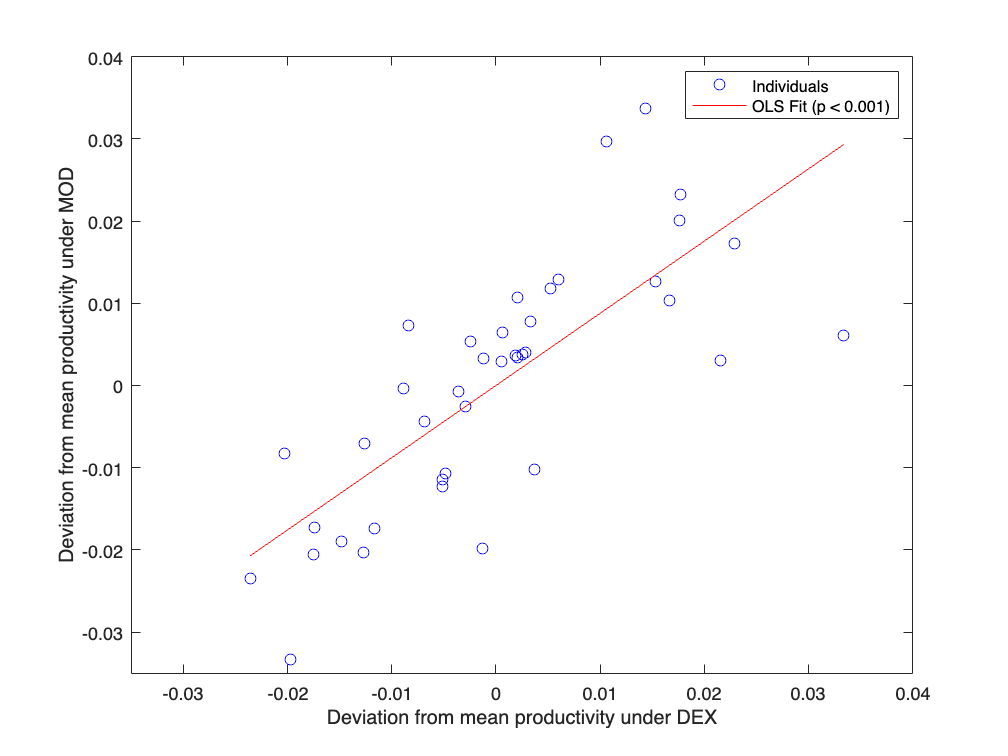

Bhat = bigX*b;
plot(B(2:4:end),Bhat,'-r')
legend('Individuals','OLS Fit (p < 0.001)')
hold off;

Figure 3d

modelspec = 'num_items_overlap_first_tn_sol_set ~ 1 + Drug + sahni_k*num_items_overlap_GA_sol + (1 | participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           5
    Random effects coefficients         40
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    num_items_overlap_first_tn_sol_set ~ 1 + Drug + sahni_k*num_items_overlap_GA_sol + (1 | participant_id)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    8602    8642.9    -4294            8588    

Fixed effects coefficients (95% CIs):
    Name                                        Estimate    SE          tStat      DF      pValue         Lower      Upper    
    {'(Intercept)'                     }           2.053     0.13819     14.856    2550     6.0347e-48     1.7821        2.324
    {'s

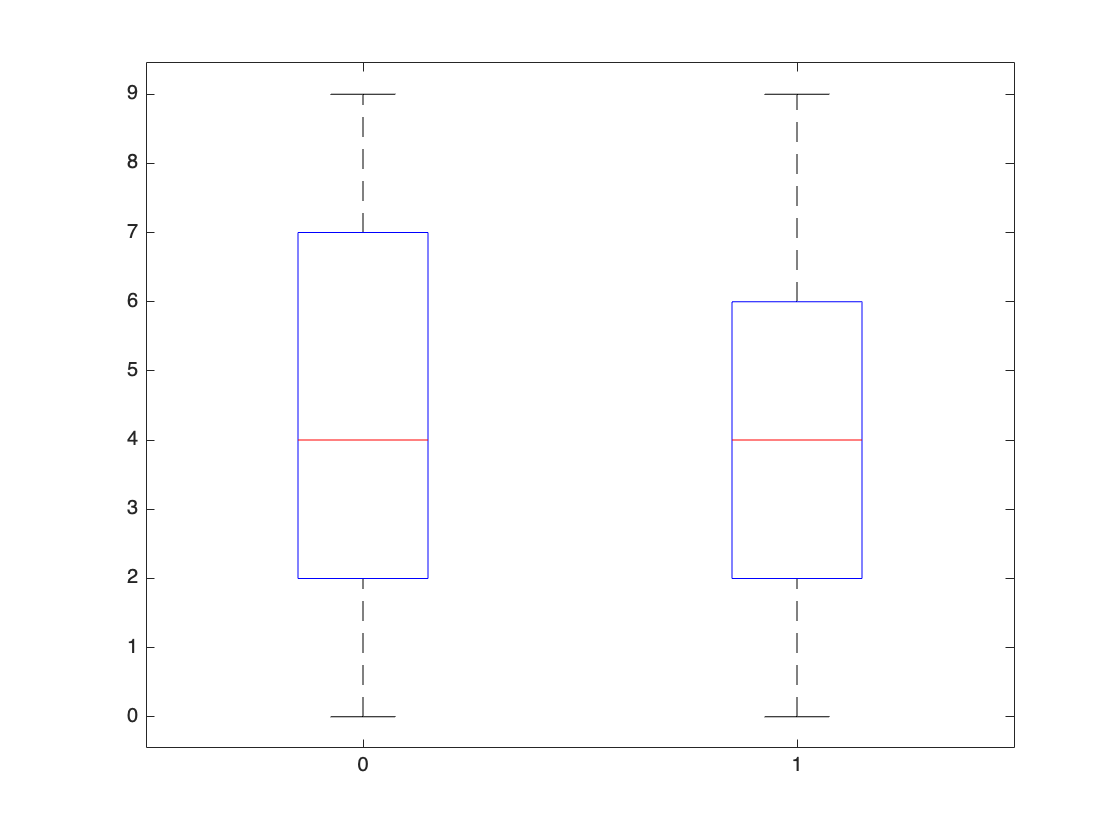


figure;
boxplot(Xall.num_items_overlap_first_tn_sol_set,Xall.Drug)

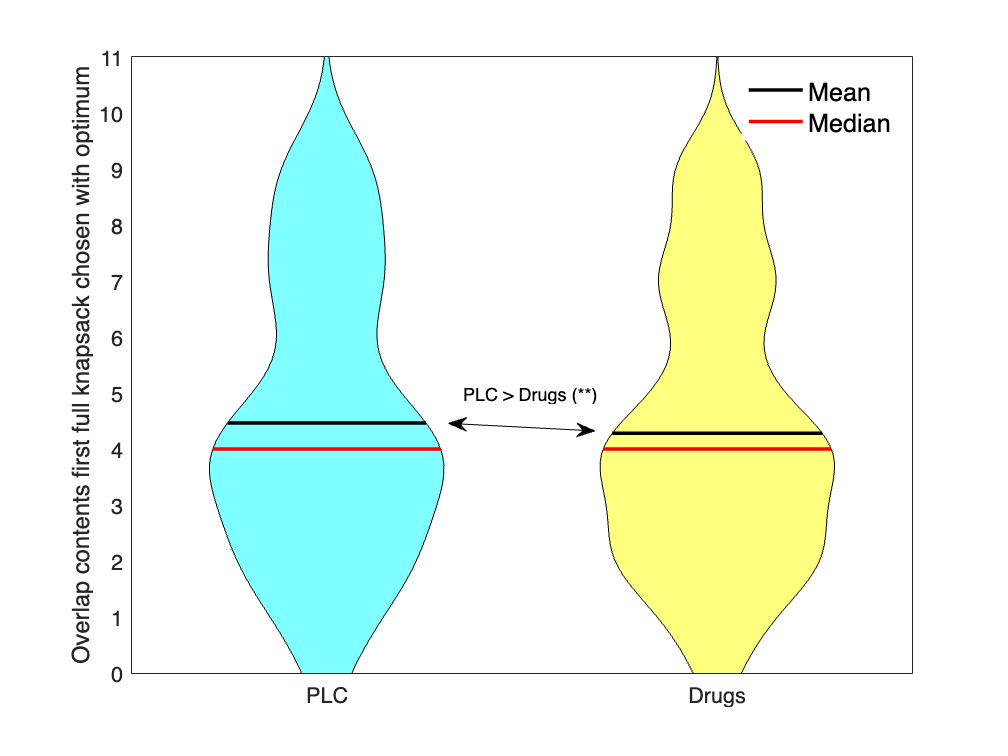


fs = find(Xall.Drug==0);
overlap0 = Xall.num_items_overlap_first_tn_sol_set(fs);

fs = find(Xall.Drug==1);
overlap1 = Xall.num_items_overlap_first_tn_sol_set(fs);

figure;
overlap = {overlap0, overlap1};
violin(overlap,'xlabel',{'PLC','Drugs'},'facecolor',[0 1 1; 1 1 0]);
axis([0.5 2.5 0 11])
ylabel('Overlap contents first full knapsack chosen with optimum')
annotation('doublearrow',[0.445,0.59],[0.44,0.43])
text(1.35,5,'PLC > Drugs (**)')